# Check peak response patterns 

Data 

2024.7.29

2024.7.30

2024.7.31

files                       =       dir('*.mat');
Dates                       =       arrayfun(@(x)x.name, files, 'UniformOutput', false);
nfiles                      =       length(Dates);

ncheck                      =       2;
ANM = extractBefore(Dates{1}, '_');

Dates = Dates(nfiles-ncheck+1:nfiles)

Dates = 2×1 cell 数组
    {'Xiaomi_MedLick_Peak_20240730_115331.mat'}
    {'Xiaomi_MedLick_Peak_20240731_131333.mat'}


Treatment = [0 0];
% Check if these labelings are correct
for i=1:length(Dates)
    man = Treatment(i);
    if man == 0
        sprintf('Saline: %s', Dates{i})
    else
        sprintf('DCZ:    %s', Dates{i})
    end
end

ans = 'Saline: Xiaomi_MedLick_Peak_20240730_115331.mat'

ans = 'Saline: Xiaomi_MedLick_Peak_20240731_131333.mat'

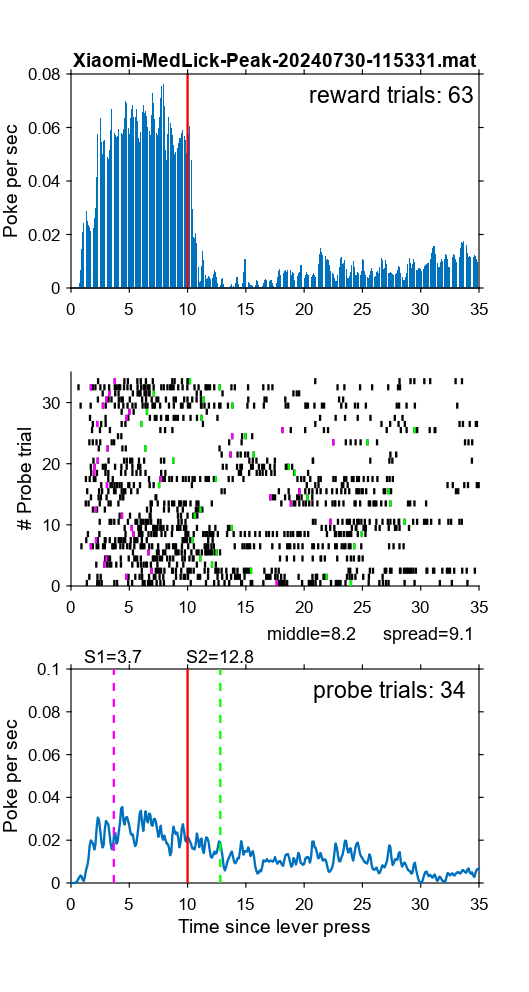

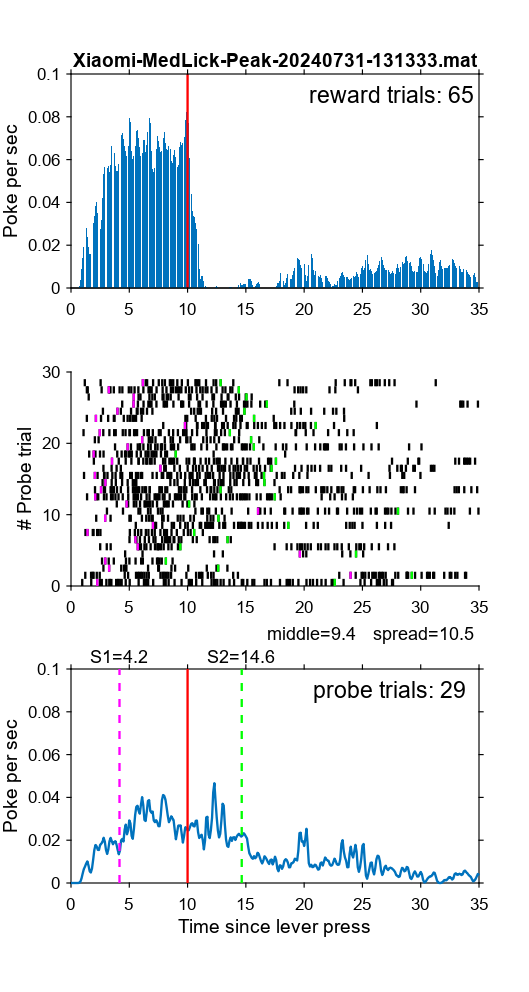

ans = 'Width at half peak (Saline) is 13.10'

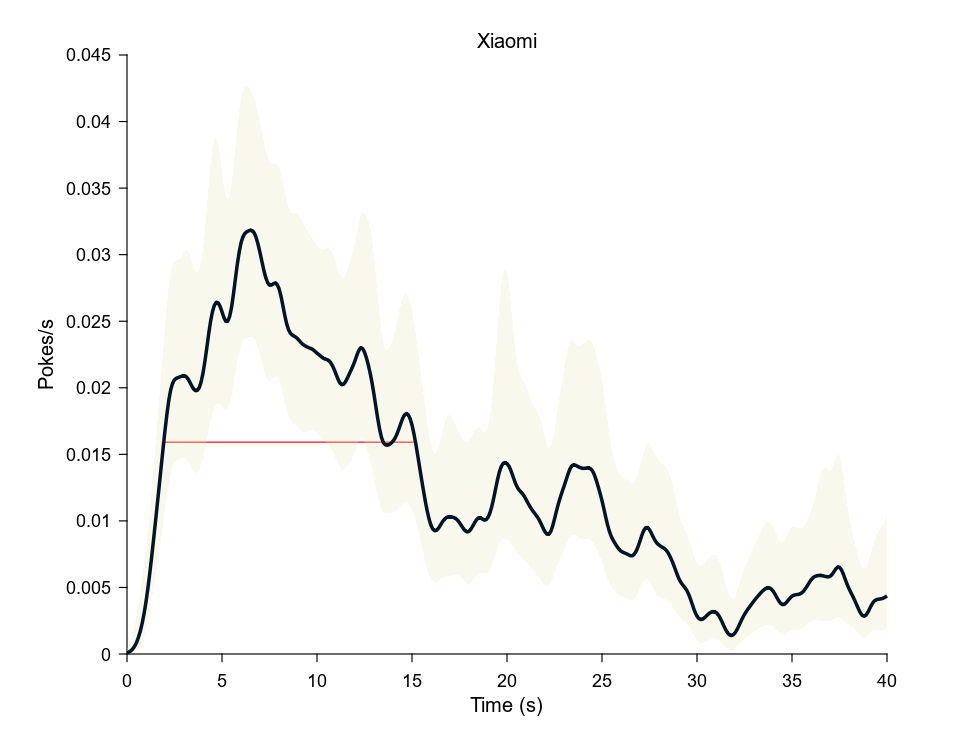

% addpath(GetParentFolder(pwd))
process_pi_cy(Dates, Treatment, ANM,...
    'printDailyFig',true,'splitReward',false,'pokeAlign','lastPress',...
    'binWidth',0.1,'maxAnalysisTime',40);